## Definieren der Rakete

clc;
clear;

m0 = 1.7819e+05; % [kg]

mn_1 = 1.1772e+05; % [kg]
mn_2 = 5.0474e+04; % [kg]
m1 = 10000; % [kg]

m8_1 = 1.0519e+05; % [kg]
m8_2 = 4.1619e+04; % [kg]

C_1 = 2.9518e+03; % [kg]
C_2 = 4.5111e+03; % [kg]

a_1 = 12.5; % [m/s]
a_2 = 10; % [m/s]

cw_1 = 0.4;
cw_2 = 0.4;
ca_1 = 0;
ca_2 = 0;
% TODO: D berechnen
D = 4;

%% Konstantenberechnung 
A_1 = D^2 * pi /4;
A_2 = D^2 * pi /4;

F_1 = m0 * a_1; % [N]
F_2 = (m0 - mn_1) * a_2; % [N]

Itot_1 = m8_1 * C_1;
Itot_2 = m8_2 * C_2;

tc_1 = Itot_1 / F_1

tc_1 = 139.4017

tc_2 = Itot_2 / F_2

tc_2 = 310.4804


mp_1 =  F_1/C_1;
mp_2 =  F_2/C_2;

## Definieren des Planeten

r0=6371000;
K=3.9658e14;
g0=9.81;
gamma0 = 90 * pi/180; 


## Stufe 1

c = [cw_1 ca_1 A_1 K mp_1, F_1 tc_1 r0];
tspan = [1 101];
y0 = [0 r0 m0 gamma0 0];

[T,Y] = ode45(@(t,y) ha2_engine(t,y,c), tspan, y0);

Y

Y = 	1.0e+06 *

         0    6.3710    0.1782    0.0000         0
       NaN       NaN    0.1763       NaN       NaN
       NaN       NaN    0.1744       NaN       NaN
       NaN       NaN    0.1725       NaN       NaN
    0.0000    6.3710    0.1706       NaN         0
       NaN       NaN    0.1688       NaN       NaN
       NaN       NaN    0.1669       NaN       NaN
       NaN       NaN    0.1650       NaN       NaN
       NaN       NaN    0.1631       NaN       NaN
       NaN       NaN    0.1612       NaN       NaN


T

T =     1.0000
    3.5000
    6.0000
    8.5000
   11.0000
   13.5000
   16.0000
   18.5000
   21.0000
   23.5000


% 
% v_1 = Y(1)
% r_1 = Y(2)
% gamma_1 = Y(4)
% angle = Y(5)
% c = [cw_2 ca_2 A_2 K mp_2, F_2 tc_2 r0];
% tspan = [tc_1 tc_2];
% y0 = [v_1 r_1 (m0 - mn_1) gamma_1 angle];
% 
% %[T,Y] = ode15s(@(t,y) ha2_engine(t,y,c), tspan, y0);

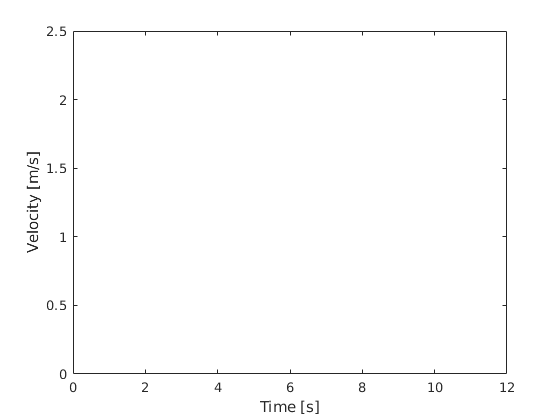

figure(1)
plot (T,Y(:,1),'r-')
ylabel ('Velocity [m/s]')
xlabel ('Time [s]')

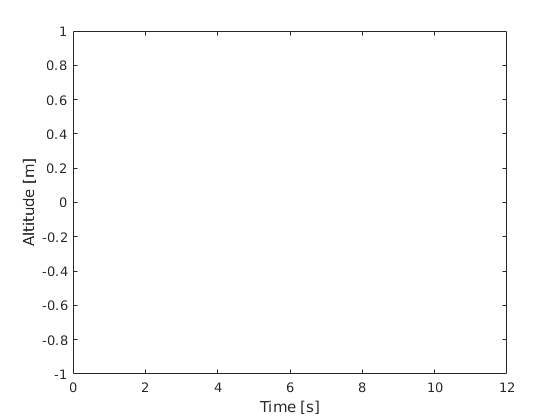


plot (T,Y(:,2)-r0,'b-')
ylabel ('Altitude [m]')
xlabel ('Time [s]')

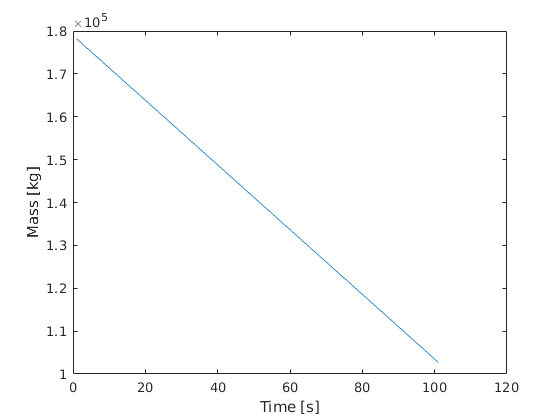

figure (4)
plot (T,Y(:,3))
ylabel ('Mass [kg]')
xlabel ('Time [s]')